# Project 4 - Generative Neural Natwork

## MNIST

clear;close all;clc;
addpath('./MNIST');
trainImagesFile = 'train-images.idx3-ubyte';
testImagesFile = 't10k-images.idx3-ubyte';
testLabelsFile = 't10k-labels.idx1-ubyte';
trainLabelsFile = 'train-labels.idx1-ubyte';

% Training set
XTrain = processMNISTimages(trainImagesFile);
YTrain = processMNISTlabels(trainLabelsFile);
numTrainImages = size(XTrain,4);

%Test set
XTest = processMNISTimages(testImagesFile);
YTest = processMNISTlabels(testLabelsFile);


## Network construction

latentDim = 2;
imageSize = [28 28 1];

encoderLG = layerGraph([
    imageInputLayer(imageSize,'Name','input_encoder','Normalization','none')
    convolution2dLayer(3, 32, 'Padding','same', 'Stride', 2, 'Name', 'conv1')
    reluLayer('Name','relu1')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv2')
    reluLayer('Name','relu2')
    fullyConnectedLayer(2 * latentDim, 'Name', 'fc_encoder')
    ]);

decoderLG = layerGraph([
    imageInputLayer([1 1 latentDim],'Name','i','Normalization','none')
    transposedConv2dLayer(7, 64, 'Cropping', 'same', 'Stride', 7, 'Name', 'transpose1')
    reluLayer('Name','relu1')
    transposedConv2dLayer(3, 64, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose2')
    reluLayer('Name','relu2')
    transposedConv2dLayer(3, 32, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose3')
    reluLayer('Name','relu3')
    transposedConv2dLayer(3, 1, 'Cropping', 'same', 'Name', 'transpose4')
    ]);

% To train both networks with a custom training loop,
encoderNet = dlnetwork(encoderLG);
decoderNet = dlnetwork(decoderLG);


## Training Options

numEpochs = 10;
miniBatchSize = 128;
% miniBatchSize = 64;
lr = 1e-3;
% lr = 1e-2;
executionEnvironment = "auto";
numIterations = floor(numTrainImages/miniBatchSize);
Iter_50_percent = floor((0.5*numTrainImages)/miniBatchSize);

iteration = 0;

% Adam Optimizer
avgGradientsEncoder = [];
avgGradientsSquaredEncoder = [];
avgGradientsDecoder = [];
avgGradientsSquaredDecoder = [];

% Stochastic Gradient Descent
% It was verified that momentum by default is set to 0.9
% momentum = 0.90;
vel_encoder = [];
vel_decoder = [];

## Epochs

for epoch = 1:numEpochs
    tic;
    for i = 1:numIterations
        iteration = iteration + 1;
        idx = (i-1)*miniBatchSize+1:i*miniBatchSize;
        XBatch = XTrain(:,:,:,idx);
        XBatch = dlarray(single(XBatch), 'SSCB');

        if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
            XBatch = gpuArray(XBatch);           
        end 
            
        [infGrad, genGrad] = dlfeval(...
            @modelGradients, encoderNet, decoderNet, XBatch);
        
        [decoderNet.Learnables, avgGradientsDecoder, avgGradientsSquaredDecoder] = ...
            adamupdate(decoderNet.Learnables, ...
                genGrad, avgGradientsDecoder, avgGradientsSquaredDecoder, iteration, lr);
        [encoderNet.Learnables, avgGradientsEncoder, avgGradientsSquaredEncoder] = ...
            adamupdate(encoderNet.Learnables, ...
                infGrad, avgGradientsEncoder, avgGradientsSquaredEncoder, iteration, lr);
    end
    elapsedTime = toc;
    
    [z, zMean, zLogvar] = sampling(encoderNet, XTest);
    xPred = sigmoid(forward(decoderNet, z));
    elbo = ELBOloss(XTest, xPred, zMean, zLogvar);
    disp("Epoch : "+epoch+" Test ELBO loss = "+gather(extractdata(elbo))+...
        ". Time taken for epoch = "+ elapsedTime + "s")    
end

Epoch : 1 Test ELBO loss = 25.8819. Time taken for epoch = 547.6842s
Epoch : 2 Test ELBO loss = 24.6736. Time taken for epoch = 218.3645s
Epoch : 3 Test ELBO loss = 24.2584. Time taken for epoch = 200.3761s
Epoch : 4 Test ELBO loss = 23.8182. Time taken for epoch = 200.2393s
Epoch : 5 Test ELBO loss = 23.4951. Time taken for epoch = 199.7726s
Epoch : 6 Test ELBO loss = 23.1601. Time taken for epoch = 199.7996s
Epoch : 7 Test ELBO loss = 22.8636. Time taken for epoch = 201.3765s
Epoch : 8 Test ELBO loss = 22.6091. Time taken for epoch = 201.5106s
Epoch : 9 Test ELBO loss = 22.4491. Time taken for epoch = 200.4626s
Epoch : 10 Test ELBO loss = 22.2922. Time taken for epoch = 200.866s


## Visualizing the results

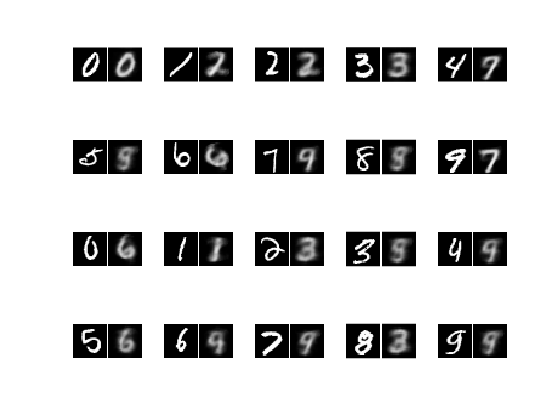

visualizeReconstruction(XTest, YTest, encoderNet, decoderNet)

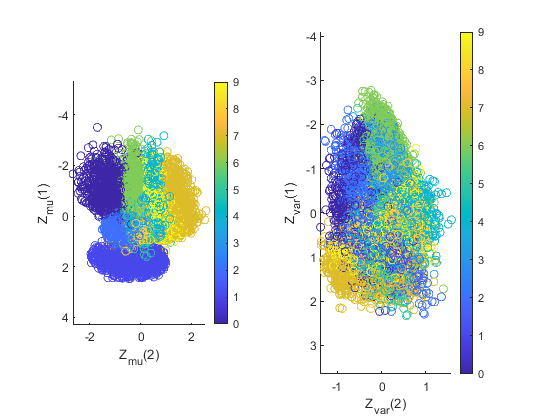

visualizeLatentSpace(XTest, YTest, encoderNet)

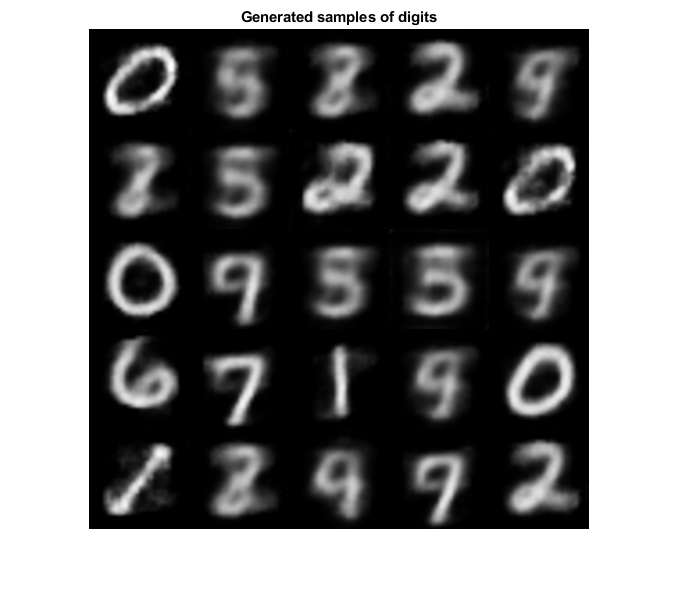

generate(decoderNet, latentDim)

## Classifier accuracy

classifier_layers = classify_layers();

% Defining the other half of MNIST data to be training on
MNIST_n = numTrainImages/2;

MNIST_images_train1 = extractdata(XTrain(:,:,1,1:MNIST_n));
MNIST_labels_train1 = YTrain(1:MNIST_n);
images_test = extractdata(XTest(:,:,1,1:10000));
labels_test = YTest(1:10000);

% p% of data will be used from the other half of MNIST train data
p = 0.2;
MN = p*(MNIST_n);
MNIST_images_train2 = XTrain(:,:,1,MNIST_n+1:MNIST_n+MN);
MNIST_labels_train2 = YTrain(MNIST_n+1:MNIST_n+MN);

options = trainingOptions('adam',...
        'MaxEpochs',3,...
        'ValidationData',{XTest,YTest});

% Training the classifier on MNIST data alone to check for 90%+ accuracy
net = trainNetwork(XTrain, YTrain,classifier_layers, options);   

% Also training it with only the second half of MNIST data for comparison 
% net = trainNetwork(MNIST_images_train2, MNIST_labels_train2,classifier_layers, options);    

predicted_labels = classify(net, XTest);
Accuracy = sum(YTest == predicted_labels)/numel(YTest);
disp(['Accuracy acheived on test set : ' num2str(Accuracy)])


## Experimenting with the classifier

% Defining the other half of MNIST data to be training on
MNIST_n = numTrainImages/2;

MNIST_images_train1 = extractdata(XTrain(:,:,1,1:MNIST_n));
MNIST_labels_train1 = YTrain(1:MNIST_n);
images_test = extractdata(XTest(:,:,1,1:10000));
labels_test = YTest(1:10000);

% p% of data will be used from the other half of MNIST train data
p = 1;
MN = p*(MNIST_n);
MNIST_images_train2 = XTrain(:,:,1,MNIST_n+1:MNIST_n+MN);
MNIST_labels_train2 = YTrain(MNIST_n+1:MNIST_n+MN);

% p% VAE generated images
count = 1;
for i = 1:(MN/10)  % Rest of the images/10
    for c=0:9
        idx = MNIST_labels_train2 == categorical(c);
        idx = find(idx);
        idx = idx(randi(numel(idx),1));
        
        X = MNIST_images_train2(:,:,:,idx);

        [z, ~, ~] = sampling(encoderNet, X);
        % Random noise added to the latent representation
        randomNoise = dlarray(randn(1,1,latentDim,1),'SSCB');
        z = z + randomNoise;
        
        XPred = sigmoid(forward(decoderNet, z));
        
%         X = gather(extractdata(X));
        generatedImages(:,:,1,count) = extractdata(XPred);
        generatedLabels(count) = MNIST_labels_train2(idx);
        count = count+1;
    end
end

% Training the classfier on MNIST data + generated images
% images_train = cat(4,MNIST_images_train2(:,:,1,1:MN),double(generatedImages));
% labels_train = [MNIST_labels_train2(1:MN);generatedLabels'];   

% Training the classifier on just the generated images
images_train = double(generatedImages);
labels_train = generatedLabels.';   

options = trainingOptions('adam',...
        'MaxEpochs',3,...
        'ValidationData',{images_test,labels_test});

net = trainNetwork(images_train,labels_train,classifier_layers,options);

% Testing the classifier
predicted_labels = classify(net, images_test);
Accuracy = sum(labels_test == predicted_labels)/numel(labels_test);
disp(['Accuracy acheived on test set : ' num2str(Accuracy)])
